## Question 1

Load the state-space matrices define the plant transfer function. 

clear; clc; close all;

load assignment_data_sc42145
sys = ss(A,B,C,D);
G_MIMO = tf(sys);
G = G_MIMO(1, 1)

G =
 
  -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
  ---------------------------------------------------------------
   s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
Continuous-time transfer function.



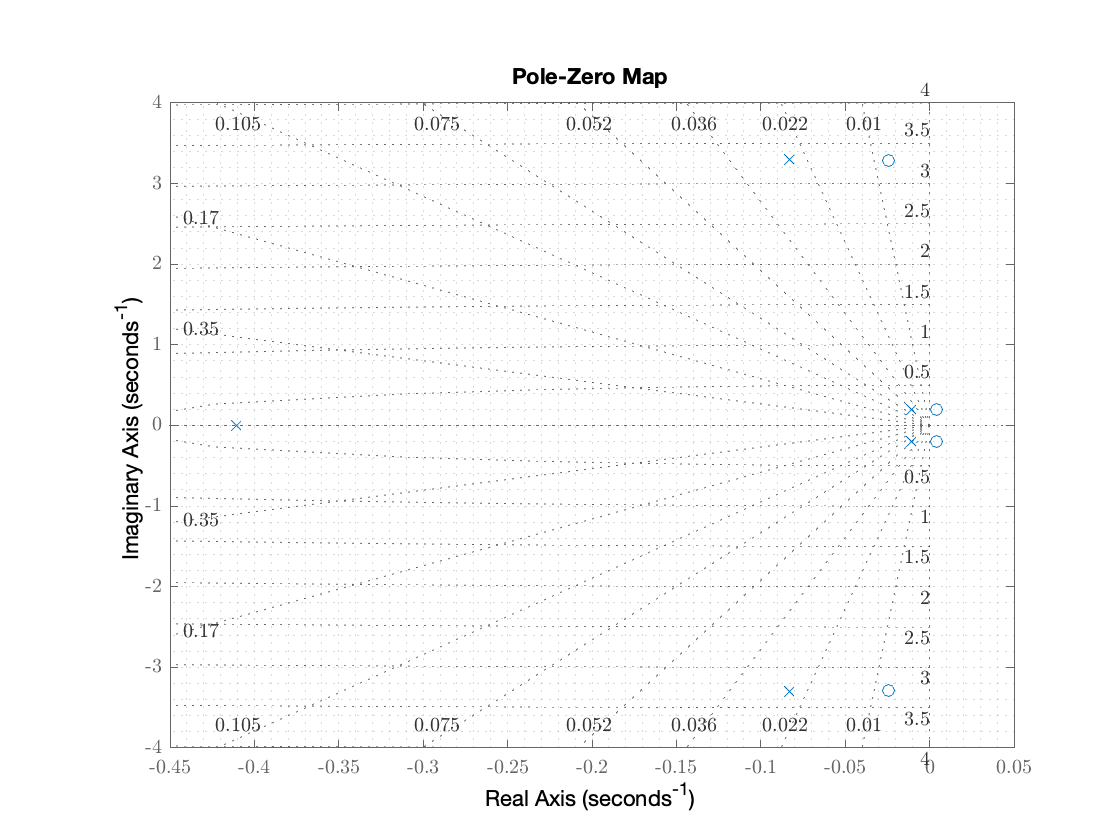

pzmap(G); grid minor

zero(G)

ans =   -0.0246 + 3.2897i
  -0.0246 - 3.2897i
   0.0038 + 0.2000i
   0.0038 - 0.2000i


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.06e-02 + 2.02e-01i     5.22e-02       2.03e-01         9.46e+01    
 -1.06e-02 - 2.02e-01i     5.22e-02       2.03e-01         9.46e+01    
 -4.10e-01                 1.00e+00       4.10e-01         2.44e+00    
 -8.32e-02 + 3.29e+00i     2.53e-02       3.29e+00         1.20e+01    
 -8.32e-02 - 3.29e+00i     2.53e-02       3.29e+00         1.20e+01    


## Question 2

### Design targets

Use a 2nd order approximation to set the frequency-response design targets.

OS = 1;
zeta_target = -log(OS/100)/sqrt(pi^2 + log(OS/100)^2);
PM_target = rad2deg(atan(2*zeta_target/...
                    sqrt(-2*zeta_target^2 + sqrt(1 + 4*zeta_target^4))));
BW_factor = 4/zeta_target*sqrt((1-2*zeta_target^2) ...
            + sqrt(4*zeta_target^4 - 4*zeta_target^2 + 2));

fprintf('Max overshoot = %f%%', OS)

Max overshoot = 1.000000%

fprintf('Damping target = %f', zeta_target);

Damping target = 0.826085

fprintf('PM target = %f', PM_target)

PM target = 70.904787

### Controller design procedure

For the controller synthesis we will progressively add control/compensation elements, assess their effects and combine them to meet the desired requirements.

#### Proportional feedback

fprintf('Steady-state gain = %f', dcgain(G))

Steady-state gain = -0.189292

The DC gain of the plant is zero - hence, we'll need negative feedback to properly track the reference step.

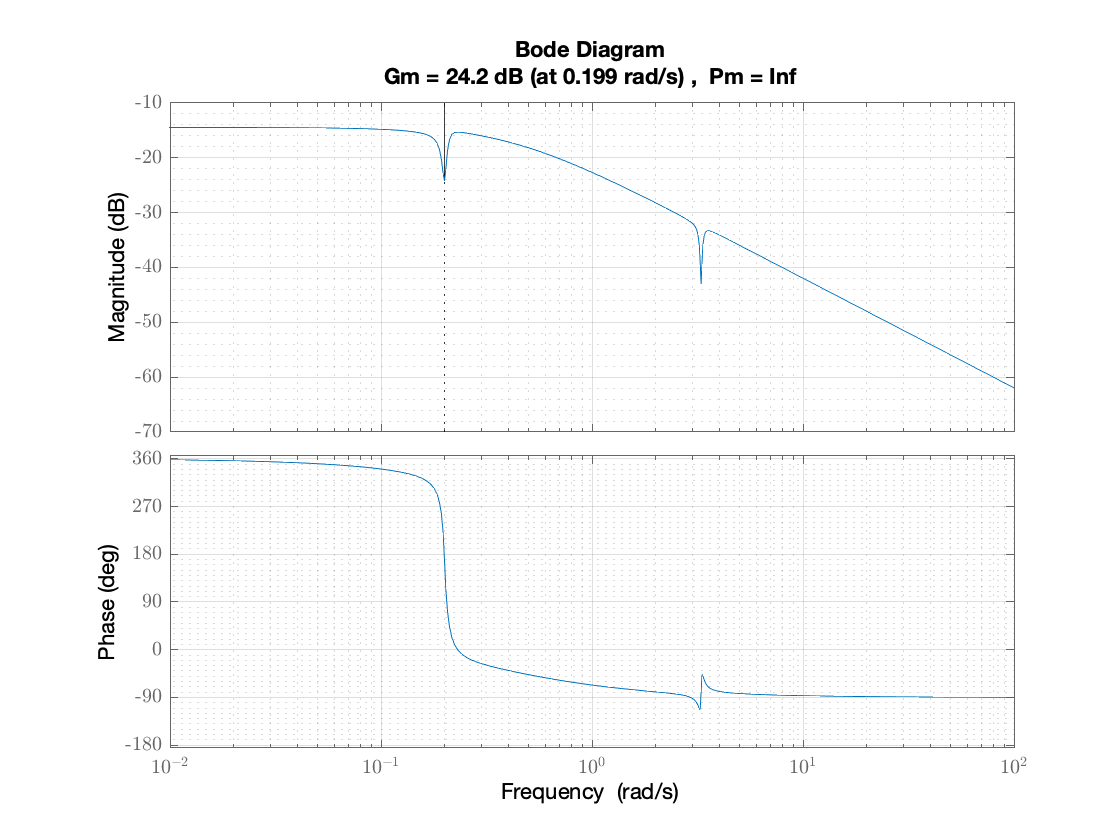

margin(-G); grid; grid minor;

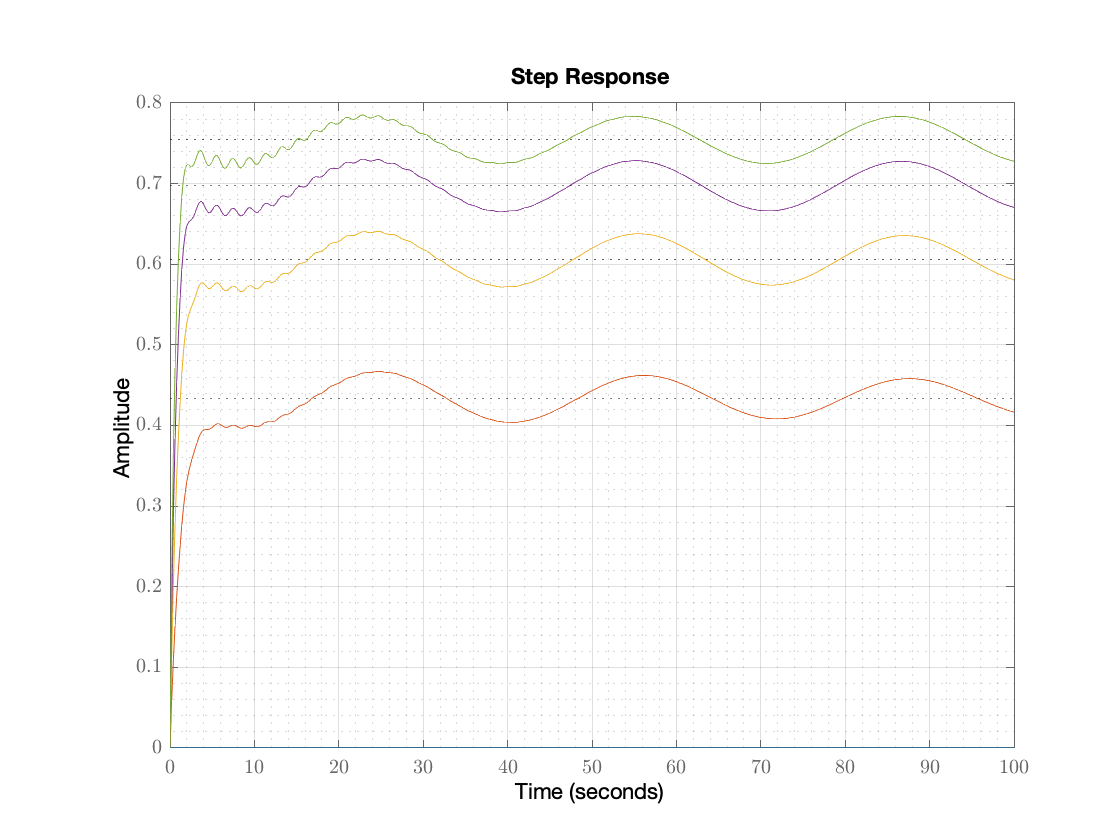

G_margins = allmargin(-G); % Compute all the margins
for K = linspace(0, G_margins.GainMargin, 5)
    step(feedback(-K*G, 1), 0:0.2:100);
    hold on; grid; grid minor;
end

Because of the gain margin, we have only limited freedom to decrease the steady-state error and make the system response faster (besides, the requirements state zero steady-state error which is not possible with pure proportional feedback anyway). Also note the presence of badly damped resonance artefacts in the step response at two frequencies (these peaks are already visible in the open loop Bode plots).

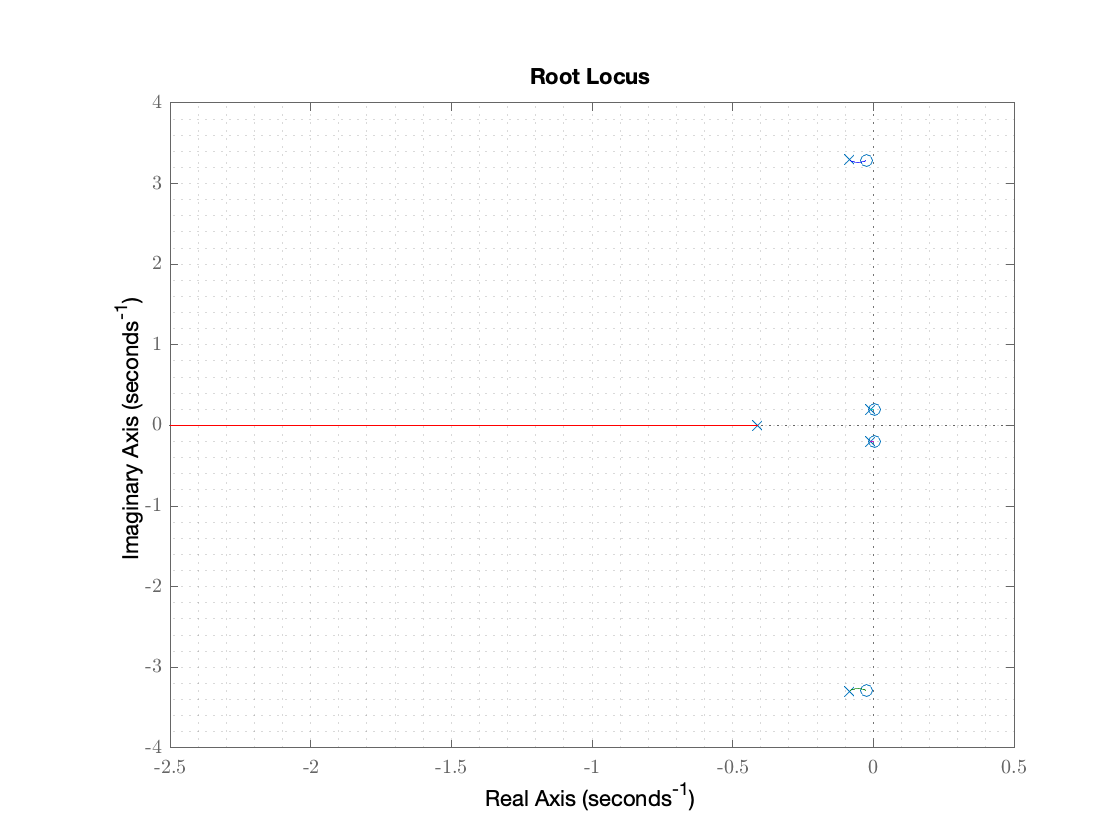

figure
rlocus(-G)

This resonance is also clear from the root locus plot, the two imaginary pole pairs move closer towards the imaginary axis, while maintaing roughly constant frequencies of 0.2 rad/s and 3.3 rad/s. (*Idea: what happens if we add more zeros to the root locus to draw the poles more into the left half-plane, hence decreasing the resonance?)*

Based on these results, this will be the subsequent strategy for the controller synthesis

- Mitigate resonance effects

- Use integral action to get rid of the steady-state error (lag is not possible since zero steady-state error is required). Please note that the infinite phase margin allows this without the immediate necessity of phase lead/D-action for stability.

- Try to improve transient behaviour by adding D-action.

Since the requirement states that the settling time should be as small as possible, we will use these strategies to create as much freedom as possible within the allowable design space limited by the overshoot and steady-state requirements in order increase the bandwidth of the system as much as possible.

#### Mitigating resonance effects: Low-pass filter

Use a second-order low-pass filter to damp the oscilliations caused by the complex pole pairs.

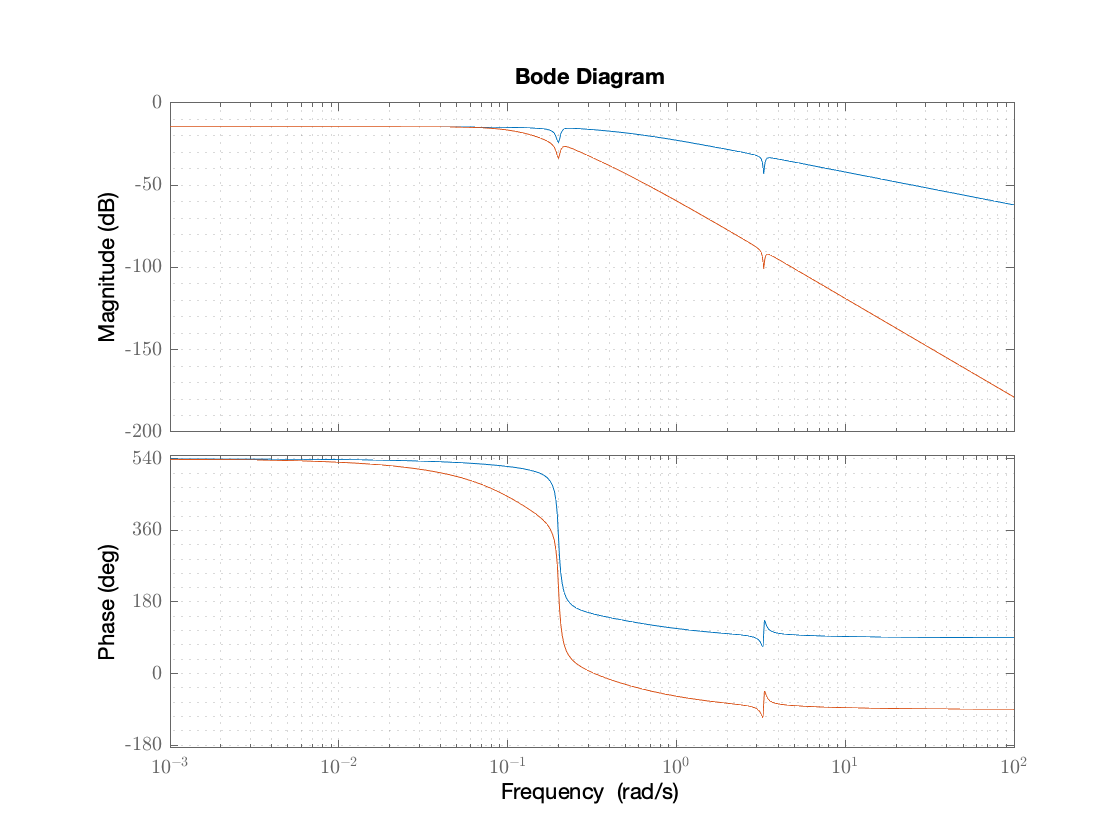

w_cut = 0.12;
lowpass = tf([0 0 w_cut^2], [1 2*w_cut*0.7 w_cut^2]);
G_filt = lowpass*G;
figure
bode(G); hold on;
bode(lowpass*G);

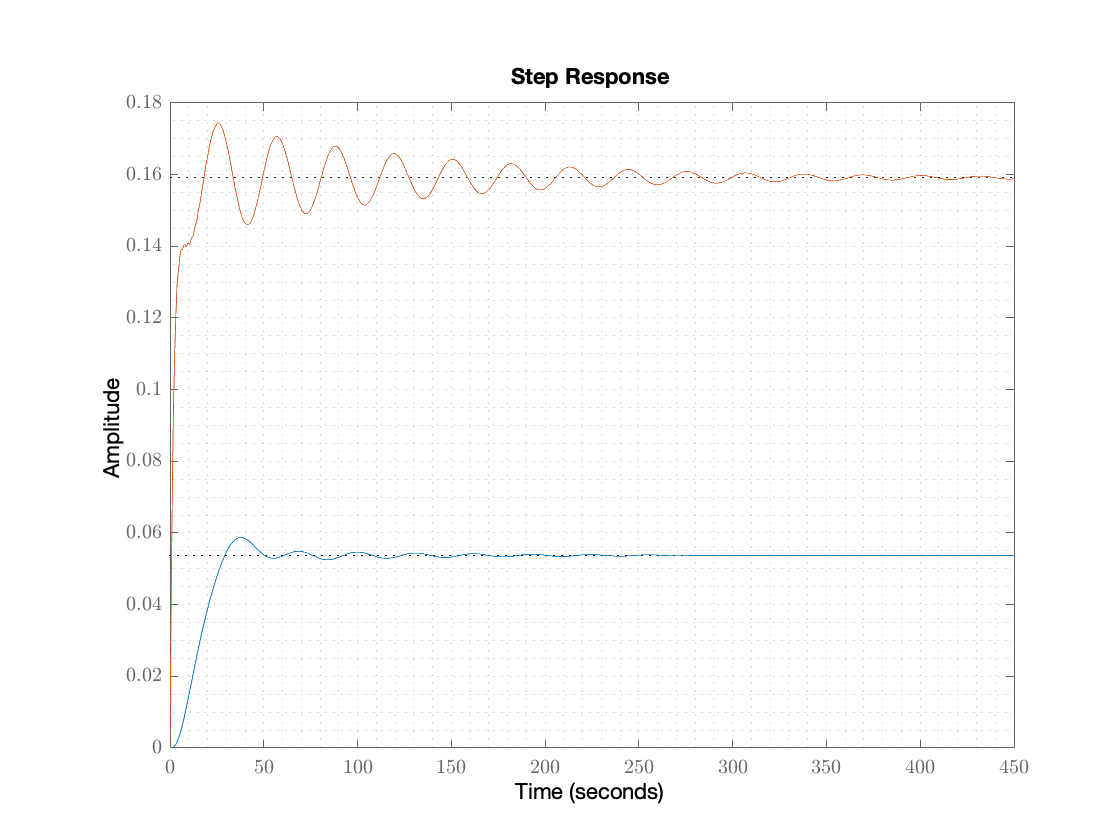

figure
step(feedback(-0.3*G_filt, 1)); hold on;
step(feedback(-G, 1))

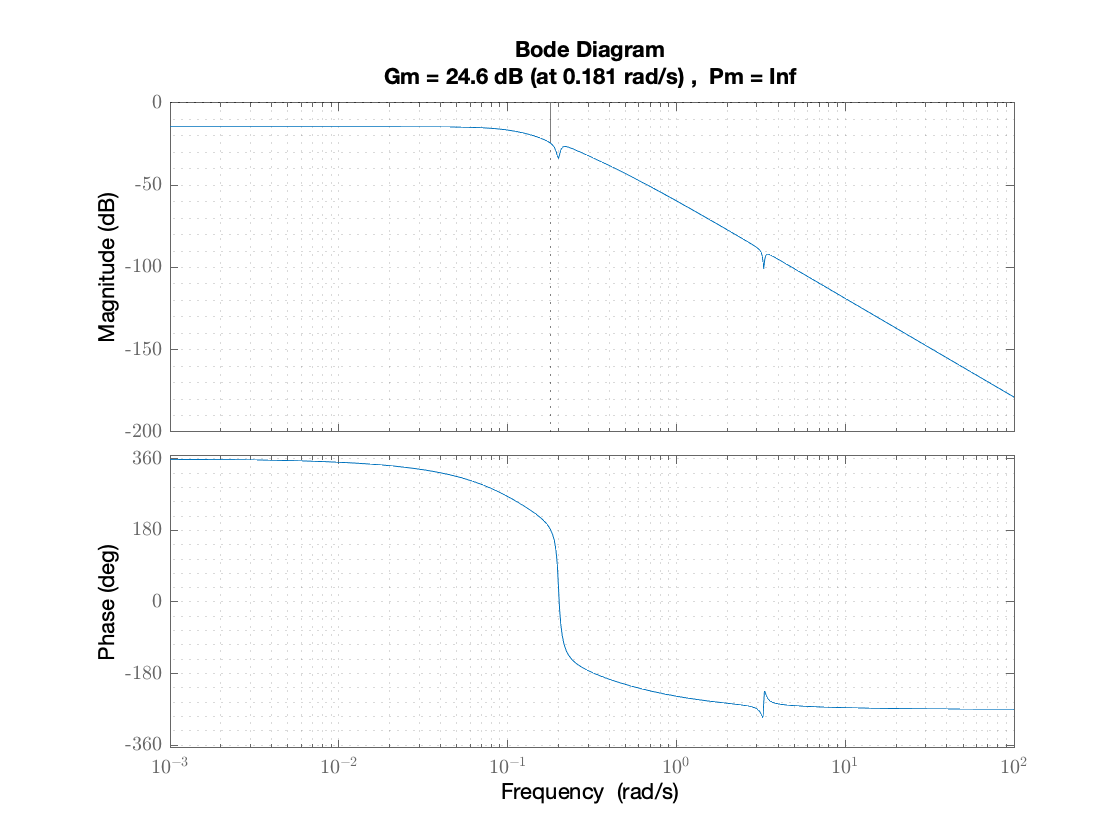

figure
margin(-G_filt)

#### Integral action: Eliminating steady-state error

The key design target for designing the integral term is to eliminate the steady-state error completely whilst minimizing the impact on the transient behaviour of the system.

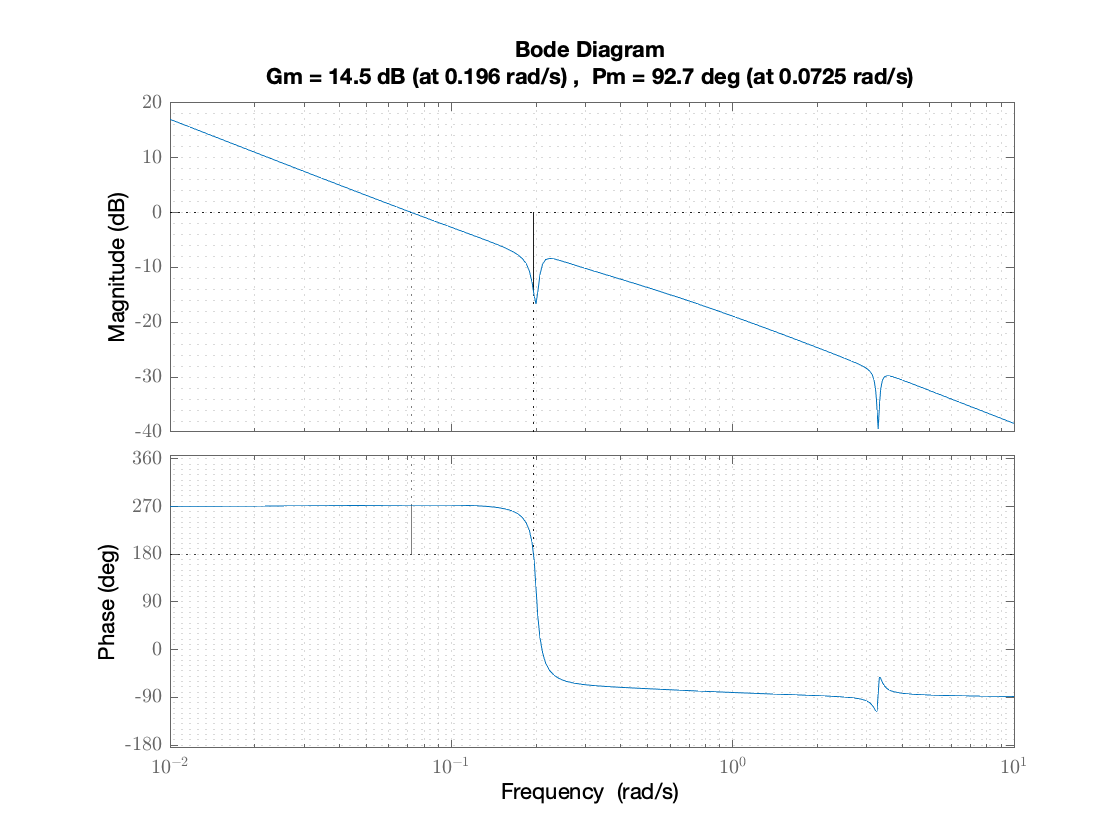

Kp = -1.5;
Ti = 4;
K_PI = pid(Kp, Kp/Ti);
figure
margin(K_PI*G);

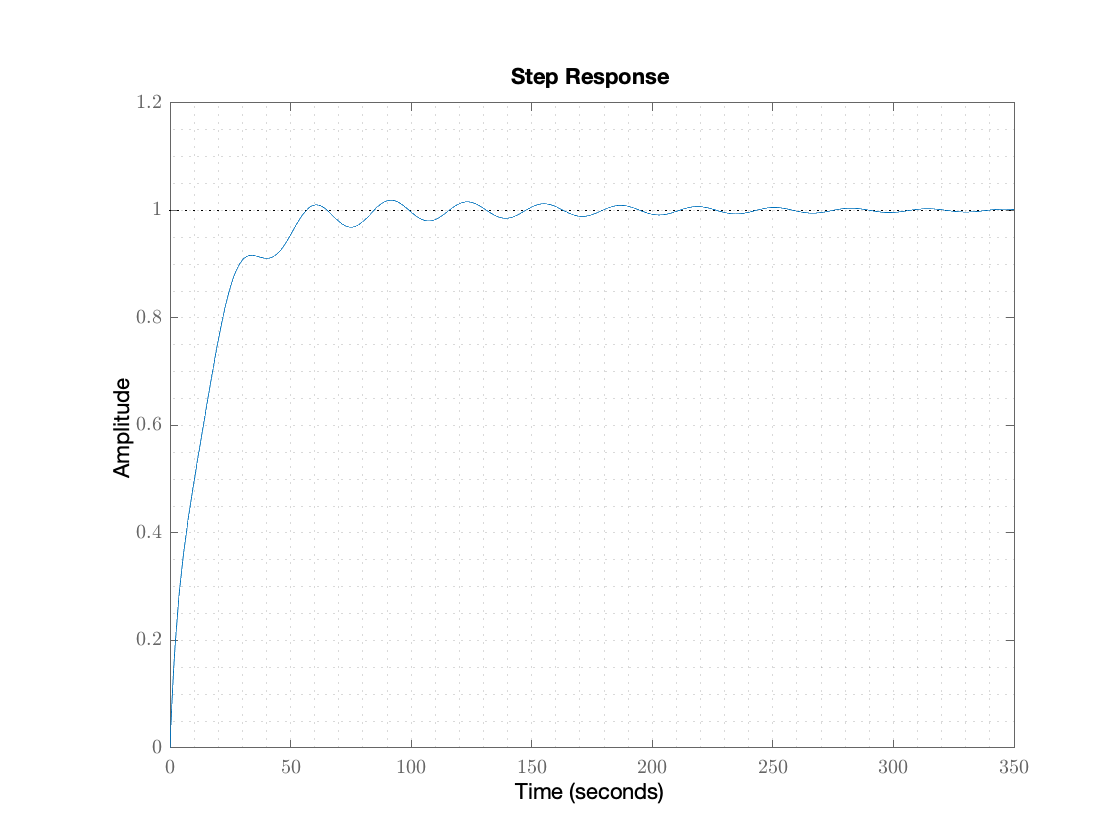

step(feedback(K_PI*G, 1))

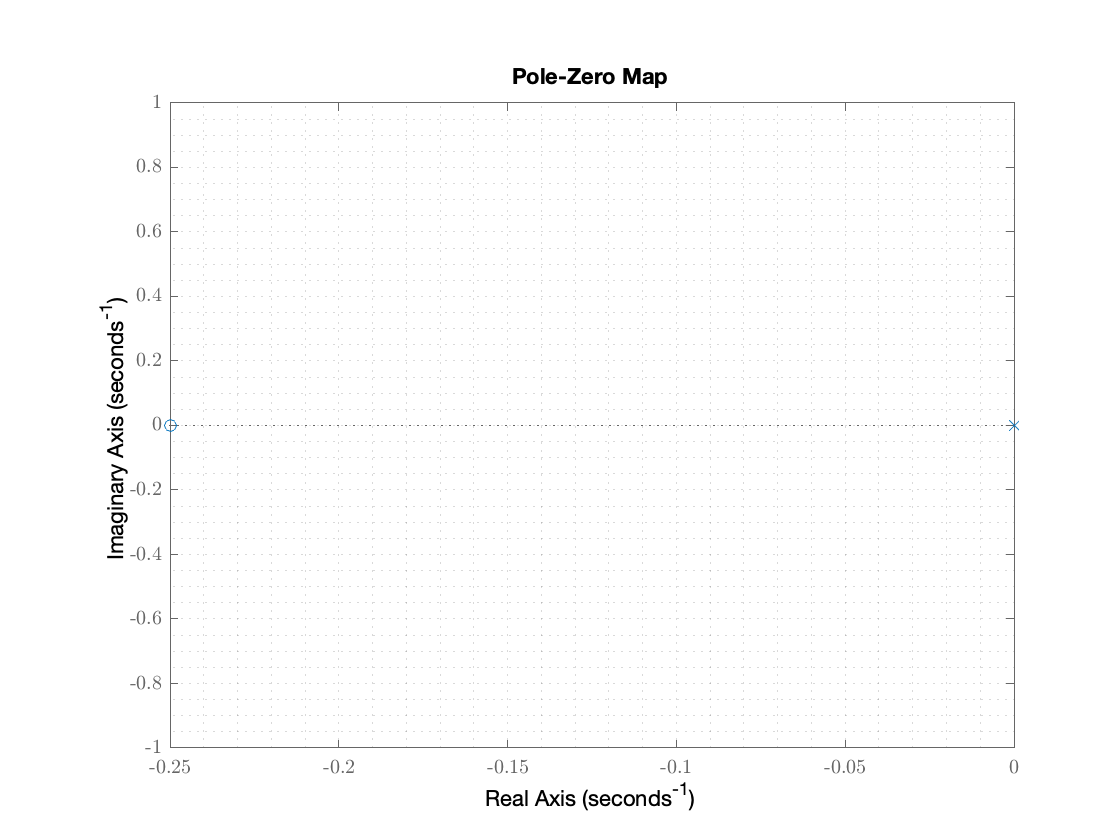

pzmap(K_PI)